# Set Options When Importing Logical Data

Use the `setvaropts` function to update properties that control the import of `logical` data. First, get the import options object for the file. Next, examine and update the options for the logical variables. Finally, import the variables using the `readtable` function.

Preview the data in `airlinesmall_subset.xlsx`. Notice the logical data in the column `Cancelled`. Only a preview of rows 30 to 40 is shown here.

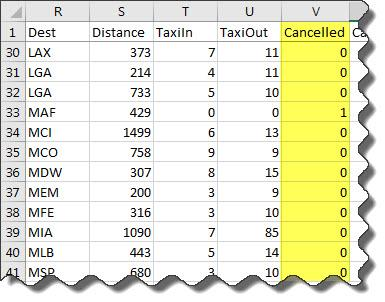

Get the import options object. 

opts = detectImportOptions('airlinesmall_subset.xlsx');

Get and examine the `VariableImportOptions` for variable `Cancelled`.

getvaropts(opts,'Cancelled')

Set the data type of the variable to `logical`. 

opts = setvartype(opts,'Cancelled','logical');

Set the `FillValue` property of the variable to replace missing values with `true`. 

opts = setvaropts(opts,'Cancelled','FillValue',true);

Select, read, and display a summary of the variable. 

opts.SelectedVariableNames = 'Cancelled';
T = readtable('airlinesmall_subset.xlsx',opts); 
summary(T)

*Copyright 2012 The MathWorks, Inc.*